% directory = "D:\workspace\DIP\oRGB\categories";
% images = "\other\STARE"  ;
% files=dir(fullfile(directory+images,'\*.png*'))

directory = "D:\workspace\DIP\oRGB\dataset\stare-photos\"

directory = "D:\workspace\DIP\oRGB\dataset\stare-photos\"


if contains(directory, "stare")
    extension = '\*.ppm*'
else
    extension = '\*.png*'
end

extension = '\*.ppm*'


files=dir(fullfile(directory,extension))

files = 397×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


%%

n1=numel(files);                                       
 

idx = 22

idx = 22

im = files(idx).name;
disp(strcat("working on: ",im))

working on: im0022.ppm


inImg = imread(fullfile(directory,im)); 
    
% inImg = imresize(inImg,0.05);

% ROI
[X, inx] = ROI(inImg);

[R,C,~] = size(inImg);
inx_bool = zeros(R*C,1);
inx_bool(inx) = 1;

scale = 5.5;
tileL = 12;
tileA = 18;
tileB = 18;
clipLimitL = 0.005;
clipLimitA = 0.01;
clipLimitB = 0.005 ;
distribution = "rayleigh";

[Z,LABp,contrast_lab,mean_lab, skew_lab,tmpp] = claheLab(X, inx,scale,[tileL tileL], [tileA tileA], [tileB tileB], [clipLimitL clipLimitA clipLimitB],distribution);
% contrast_lab
% mean_lab
% skew_lab


% meanRGB = round(mean(tmp3(inx,:)),0)

% gcf = getGlobalContrastFactor(tmp(:,:,2))
% loe = LOE(X, tmp)
% contrastRGB = round(std(double(tmp3(inx,:))), 2)
% m3 = m3colorfulness(tmp3)
% gcf = getGlobalContrastFactor(tmp(:,:,2))


tmp = uint8(tmpp*255);
tmp3 = reshape(tmp,[],3);
tmp4 = tmp3;
tmp4(~inx_bool,:) = 0;
rgb = reshape(tmp4,size(inImg));
qssim_score = qssim(inImg,rgb)

qssim_score = 0.7435

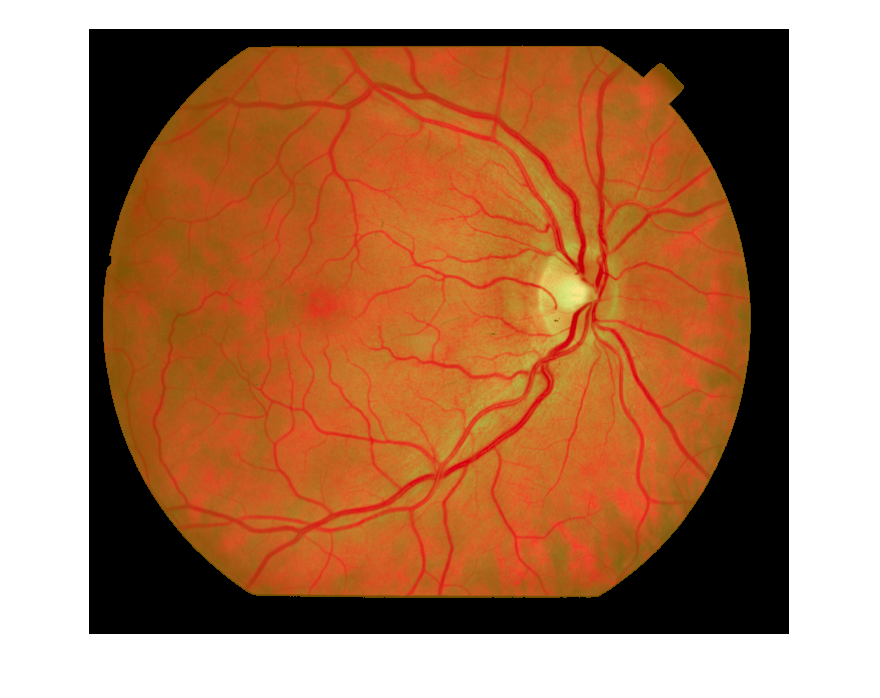

% tmp_qssim
% 
% if qssim_score > tmp_qssim
%     tmp_qssim = qssim_score;
% end

tmp = uint8(Z*255);
tmp3 = reshape(tmp,[],3);
tmp4 = tmp3;
tmp4(~inx_bool,:) = 0;
rgb = reshape(tmp4,size(inImg));
figure, imshow(rgb)


% Y = reshape(X,[],3);
% figure, histogramRGB(Y(inx,:),256)
% figure, histogramRGB(tmp4(inx,:),256)

    
%% save to file
%     im = split(im,".");
%     im = strcat(dest_path,"\",im(1),".png");
%     imwrite(Z,im);

